# Clustering & Classification

**Evaluation: Macro F1 Score, Accuracy, Recall, Precision and Confusion matrix.**

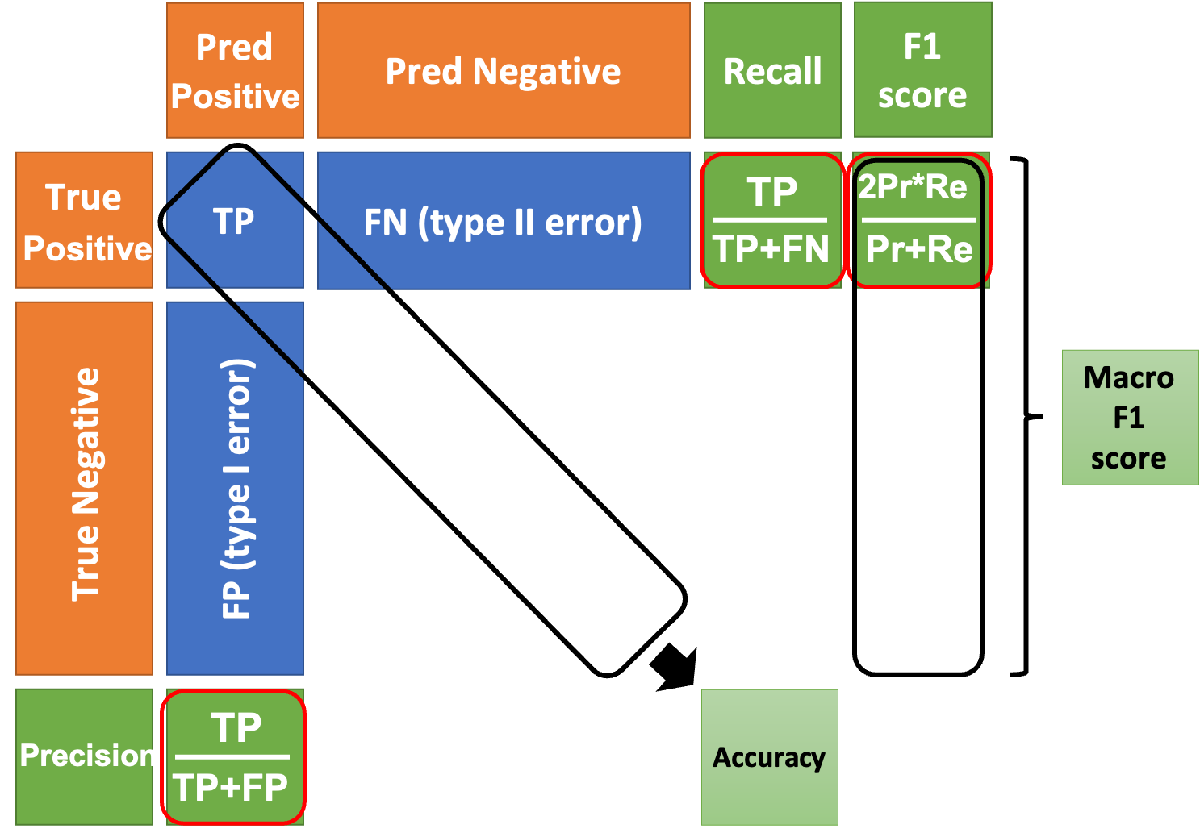

## K-means (Spectral clustering)

**K-means is a unsupervised learning.**

- The database contains 150 iris flower infomation. Each data has 4 information, sepal length, sepal width, petal length and petal width.

- There are 3 classes, Setosa, Versicolour and Virginica. Each class contains 50 data.

clc; clear; close all;
% addpath('../src', '../data')
abs_cur_dic = fileparts(fullfile(pwd));
addpath([abs_cur_dic, '/data'])
addpath([abs_cur_dic, '/src'])
addpath([abs_cur_dic, '/demo'])
% load fisheriris
load("irismat.mat")
bandwidth = 3;
num_eigvec = 3; % how many feature you hope to use
fix_random_seed = true;
if fix_random_seed
    rng(1); % For reproducibility
end
[U, S] = DMapBasic(meas, 150, num_eigvec, bandwidth);

Step 1: Construct bandwidth of kernel function.
(info) No self-loop
(info) The bandwidth is given.
(info) There are no isolated point.
(info) The median number of points in bandwidth neighborhood is 124.
(info) The first 10% number of points in bandwidth neighborhood is 99.
Step 2: Construct affinity matrix
Step 3: Ignore the probability density function
Step 4: Solve the eigenvector


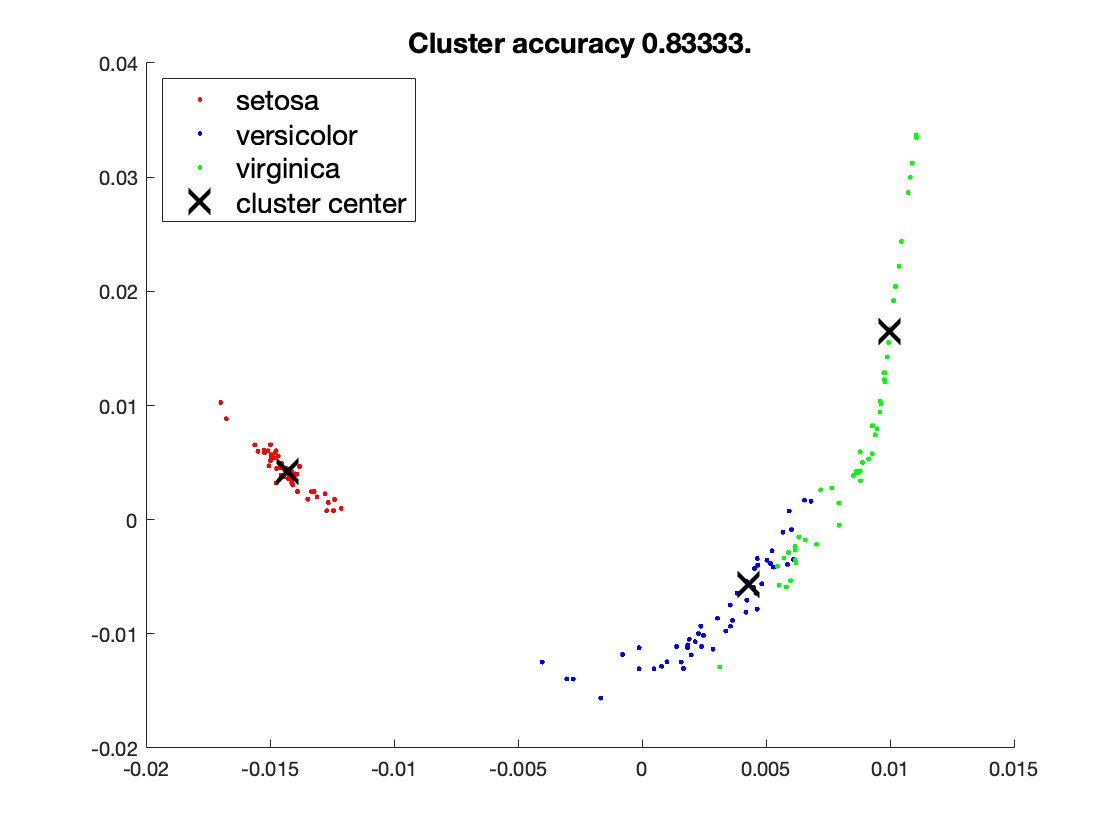

[class_idx, class_center] = kmeans(U, 3);
acc = cluster_acc(species, class_idx);

figure
hold on
plot(U(species==1, 1), U(species==1, 2), 'r.')
plot(U(species==2, 1), U(species==2, 2), 'b.')
plot(U(species==3, 1), U(species==3, 2), 'g.')
plot(class_center(:, 1), class_center(:, 2), 'kx', 'MarkerSize', 15, 'LineWidth',3)
legend({'setosa', 'versicolor', 'virginica', 'cluster center'}, 'Location','northwest', 'FontSize', 14)
title(['Cluster accuracy ', num2str(acc), '.'], 'FontSize', 14)
hold off

## Support vector machine

**SVM is a supervised learning.**

There are two parameters, box constraint and kernel scale. Note that kernel scale is not equal to bandwidth, $k(x, y)=\exp\left(-\gamma\|x-y\|^2\right)$, where kernel scale is $\gamma$. Please refer to this [website](https://www.quora.com/Support-Vector-Machines-How-do-I-choose-a-kernel-scale-parameter) for more detail.

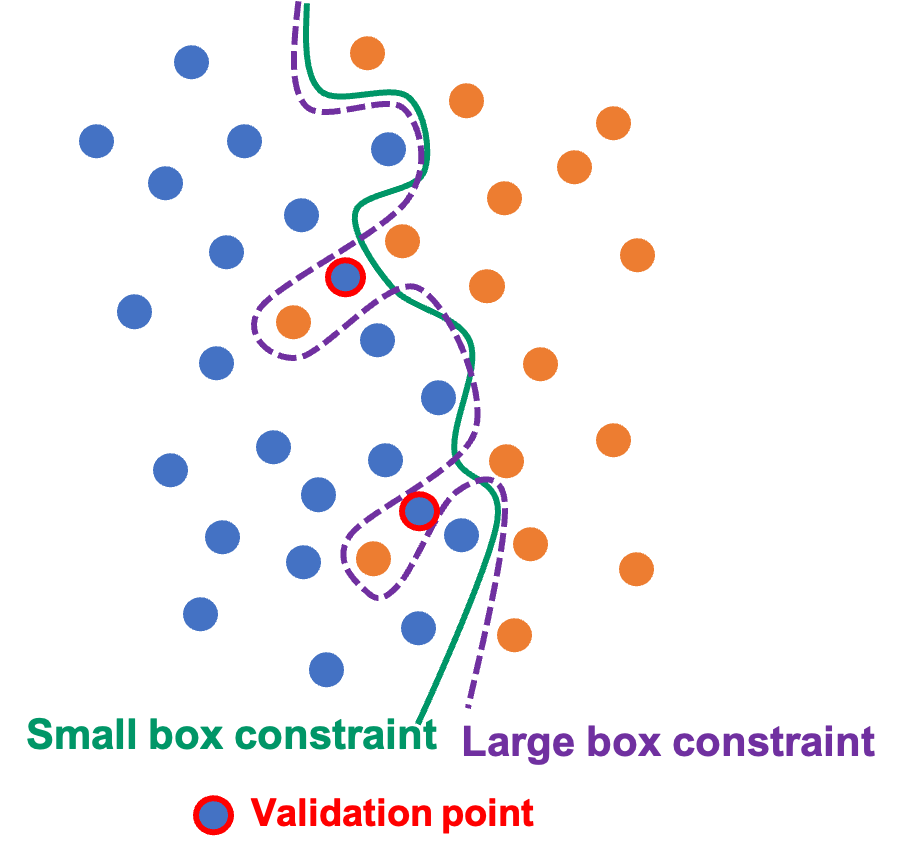

clc; clear; close all;
bandwidth = 3;
num_eigvec = 5; % how many feature you hope to use
% addpath('../src', '../data')
abs_cur_dic = fileparts(fullfile(pwd));
addpath([abs_cur_dic, '/data'])
addpath([abs_cur_dic, '/src'])
addpath([abs_cur_dic, '/demo'])
% load fisheriris
load("irismat.mat")
X = meas;
Y = species;
n = size(X, 1);
Y_hot = zeros(n, 3);
for i = 1:3
    Y_hot(Y==i, i) = 1;
end

[U, S] = DMapBasic(X, 150, num_eigvec, bandwidth);

Step 1: Construct bandwidth of kernel function.
(info) No self-loop
(info) The bandwidth is given.
(info) There are no isolated point.
(info) The median number of points in bandwidth neighborhood is 124.
(info) The first 10% number of points in bandwidth neighborhood is 99.
Step 2: Construct affinity matrix
Step 3: Ignore the probability density function
Step 4: Solve the eigenvector


### Evaluation on ONE validation set

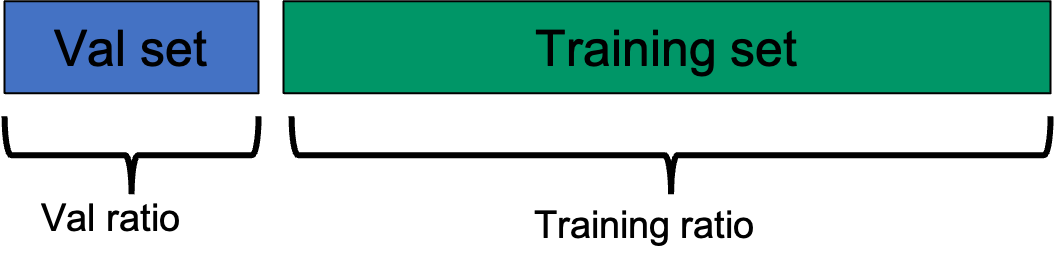

% split train and validation set
train_ratio = 0.8;
box_constraint = 1; % cost of mis-classification
kernel_scale_gamma = 10;

[train_idx, val_idx] = Split_Set(n, train_ratio);

% SVM
template = templateSVM('KernelFunction', 'gaussian', ...
    'PolynomialOrder', [], 'KernelScale', kernel_scale_gamma, ...
    'BoxConstraint', box_constraint, 'Standardize', true);

model = fitcecoc(U(train_idx, :), Y(train_idx, :), ...
    'Learners', template, ...
     'Coding', 'onevsone', ...
     'ClassNames', [1; 2; 3]);
 
[~, train_scores] = predict(model, U(train_idx, :));
[~, conf_mat] = confusion(Y_hot(train_idx, :)', train_scores');

acc = sum(diag(conf_mat)) / sum(conf_mat(:));
disp(['Training accuracy = ' num2str(acc)])

Training accuracy = 0.92562



[~, val_scores] = predict(model, U(val_idx, :));
[~, conf_mat] = confusion(Y_hot(val_idx, :)', val_scores');

[cell_info, ~, ~, ~] = CM2Info(conf_mat, {'seto', 'vers', 'virg'});
disp('The following is confusion matrix of validation set')

The following is confusion matrix of validation set


disp(cell_info)

    {0×0 double         }    {'Predict-seto'}    {'Predict-vers'}    {'Predict-virg'}    {'PR'      }    {'RE'      }    {'F1'      }
    {'Target-seto (31%)'}    {'9 (100%)'    }    {'0 (0%)'      }    {'0 (0%)'      }    {[       1]}    {[       1]}    {[       1]}
    {'Target-vers (31%)'}    {'0 (0%)'      }    {'9 (100%)'    }    {'0 (0%)'      }    {[  0.6429]}    {[       1]}    {[  0.7826]}
    {'Target-virg (38%)'}    {'0 (0%)'      }    {'5 (45%)'     }    {'6 (55%)'     }    {[       1]}    {[  0.5455]}    {[  0.7059]}
    {0×0 double         }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double}    {0×0 double}    {0×0 double}
    {'Accuracy: 0.8276' }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double}    {0×0 double}    {0×0 double}
    {'Macro F1: 0.8295' }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double}    {0×0 double}    {0×0 double}



### Evaluation on k-folds cross validation.

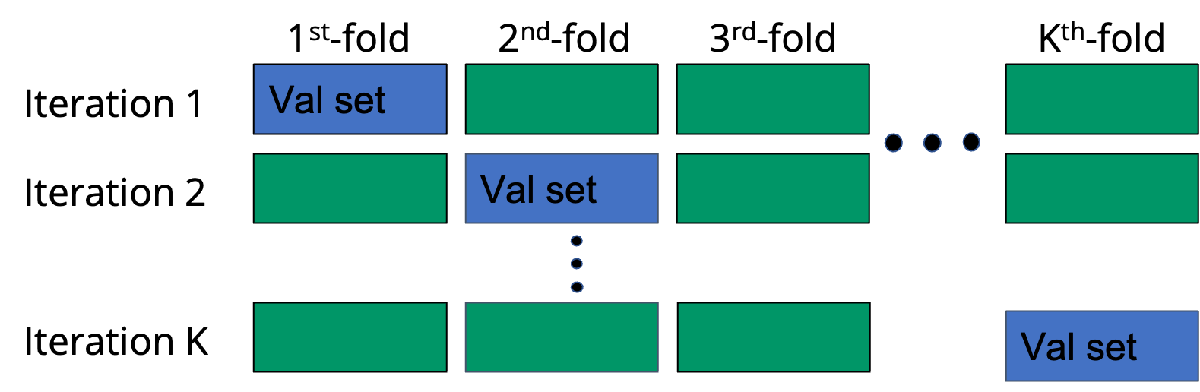

% split train and validation set
k_fold = 8;
box_constraint = 1; % cost of mis-classification
kernel_scale_gamma = 1;

[train_idices, val_idices] = Split_Set(n, k_fold);

% apply K-fold validation
val_accs = [];
val_f1s = [];
conf_mats = zeros(3); % sum over all validation confusion matrices
for i = 1:k_fold
    train_idx = train_idices{i};
    val_idx = val_idices{i};
    
    % SVM
    template = templateSVM('KernelFunction', 'gaussian', ...
        'PolynomialOrder', [], 'KernelScale', kernel_scale_gamma, ...
        'BoxConstraint', box_constraint, 'Standardize', true);
    
    % train
    model = fitcecoc(U(train_idx, :), Y(train_idx, :), ...
        'Learners', template, ...
         'Coding', 'onevsone', ...
         'ClassNames', [1; 2; 3]);
    
    [~, train_scores] = predict(model, U(train_idx, :));
    [~, conf_mat] = confusion(Y_hot(train_idx, :)', train_scores');
    train_acc = sum(diag(conf_mat)) / sum(conf_mat(:));

    % evaluation
    [~, val_scores] = predict(model, U(val_idx, :));
    [~, conf_mat] = confusion(Y_hot(val_idx, :)', val_scores');
    [val_f1, val_acc] = CM2MacroF1(conf_mat);
    
    disp_str = sprintf('[ %d / %d ]: Training accuracy = %.3f, Validation accuracy = %.3f', i, k_fold, train_acc, val_acc);
    disp(disp_str)
    
    % store all info
    val_f1s = [val_f1s, val_f1];
    val_accs = [val_accs, val_acc];
    conf_mats = conf_mats+conf_mat;
end

[ 1 / 8 ]: Training accuracy = 0.962, Validation accuracy = 1.000
[ 2 / 8 ]: Training accuracy = 0.969, Validation accuracy = 0.947
[ 3 / 8 ]: Training accuracy = 0.962, Validation accuracy = 0.947
[ 4 / 8 ]: Training accuracy = 0.962, Validation accuracy = 0.842
[ 5 / 8 ]: Training accuracy = 0.977, Validation accuracy = 0.895
[ 6 / 8 ]: Training accuracy = 0.962, Validation accuracy = 1.000
[ 7 / 8 ]: Training accuracy = 0.970, Validation accuracy = 0.889
[ 8 / 8 ]: Training accuracy = 0.962, Validation accuracy = 0.944


[cell_info, ~, ~] = CM2Info(conf_mats, {'seto', 'vers', 'virg'});
disp('The following is confusion matrix of validation set')

The following is confusion matrix of validation set


disp(cell_info)

    {0×0 double         }    {'Predict-seto'}    {'Predict-vers'}    {'Predict-virg'}    {'PR'      }    {'RE'      }    {'F1'      }
    {'Target-seto (33%)'}    {'48 (96%)'    }    {'0 (0%)'      }    {'2 (4%)'      }    {[  0.9796]}    {[  0.9600]}    {[  0.9697]}
    {'Target-vers (33%)'}    {'0 (0%)'      }    {'48 (96%)'    }    {'2 (4%)'      }    {[  0.9057]}    {[  0.9600]}    {[  0.9320]}
    {'Target-virg (33%)'}    {'1 (2%)'      }    {'5 (10%)'     }    {'44 (88%)'    }    {[  0.9167]}    {[  0.8800]}    {[  0.8980]}
    {0×0 double         }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double}    {0×0 double}    {0×0 double}
    {'Accuracy: 0.9333' }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double}    {0×0 double}    {0×0 double}
    {'Macro F1: 0.9332' }    {0×0 double    }    {0×0 double    }    {0×0 double    }    {0×0 double}    {0×0 double}    {0×0 double}



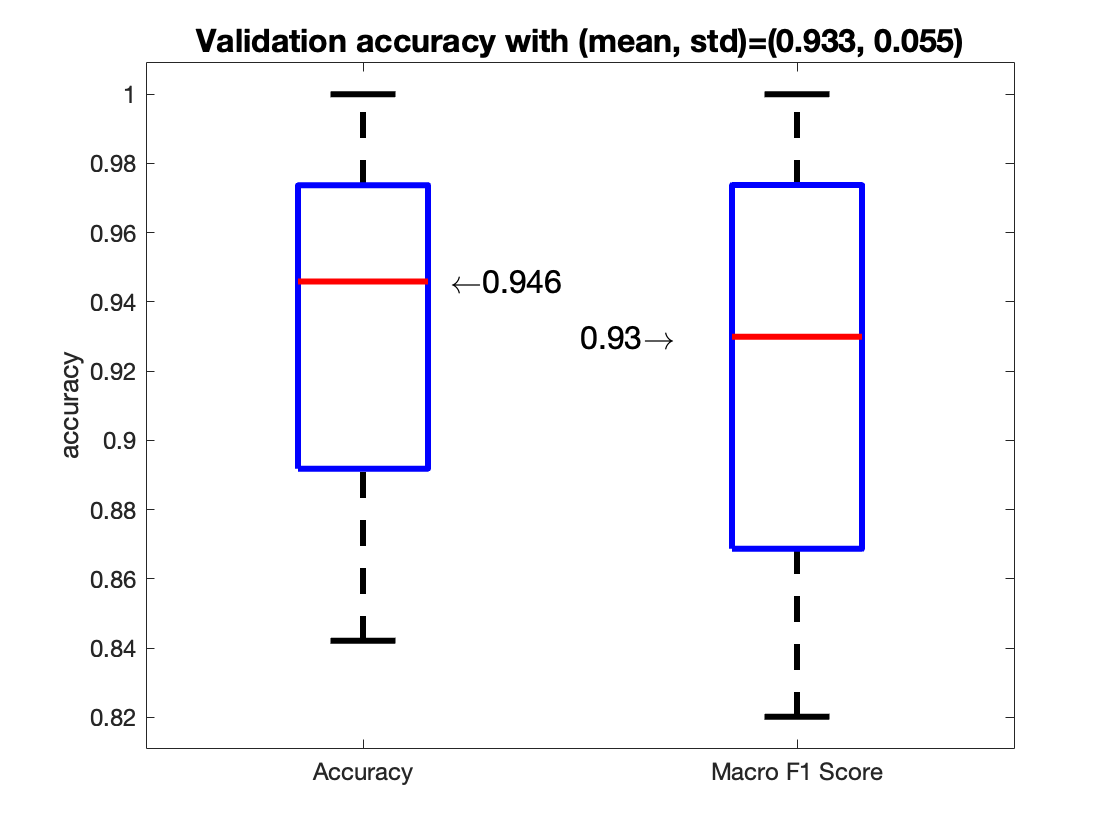

% plot validation accuracy from k-fold validation set
figure
h = boxplot([val_accs', val_f1s'], 'Labels', {'Accuracy','Macro F1 Score'});
text(1.2, median(val_accs),['\leftarrow', num2str(round(median(val_accs), 3))], 'FontSize', 16)
text(1.5, median(val_f1s),[num2str(round(median(val_f1s), 3)), '\rightarrow'], 'FontSize', 16)
ylabel('accuracy')
set(h,'LineWidth', 3)
set(gca,'FontSize',12)
title(['Validation accuracy with (mean, std)=(', num2str(round(mean(val_accs), 3)), ', ' num2str(round(std(val_accs), 3)), ')'], 'Fontsize', 16)

## EEG spectrum classification via SVM

**Task**: Predict sleep stage

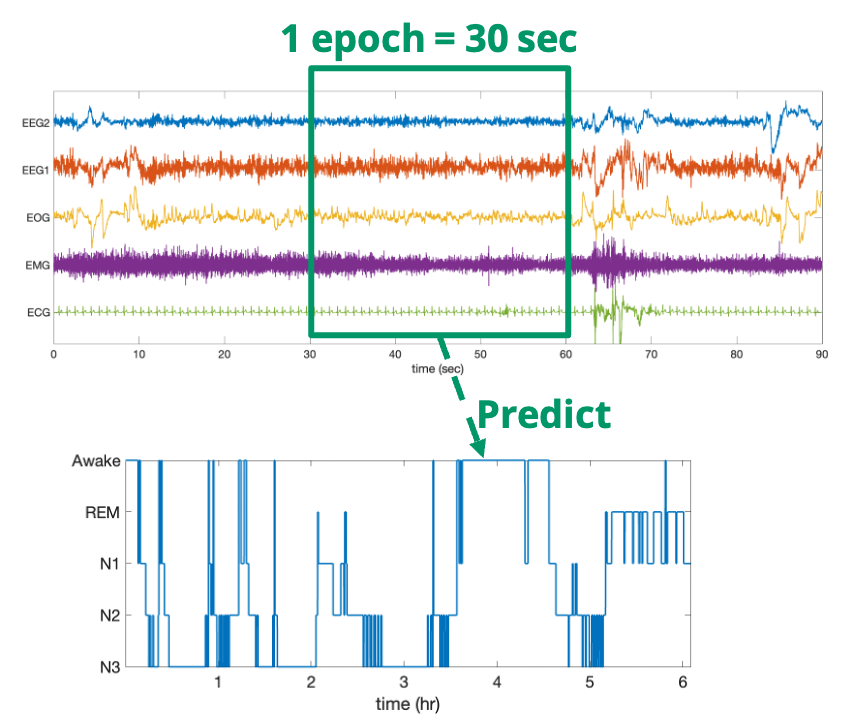

**Methodology**: Here, the EEG signals data are prepocessed by scattering transform

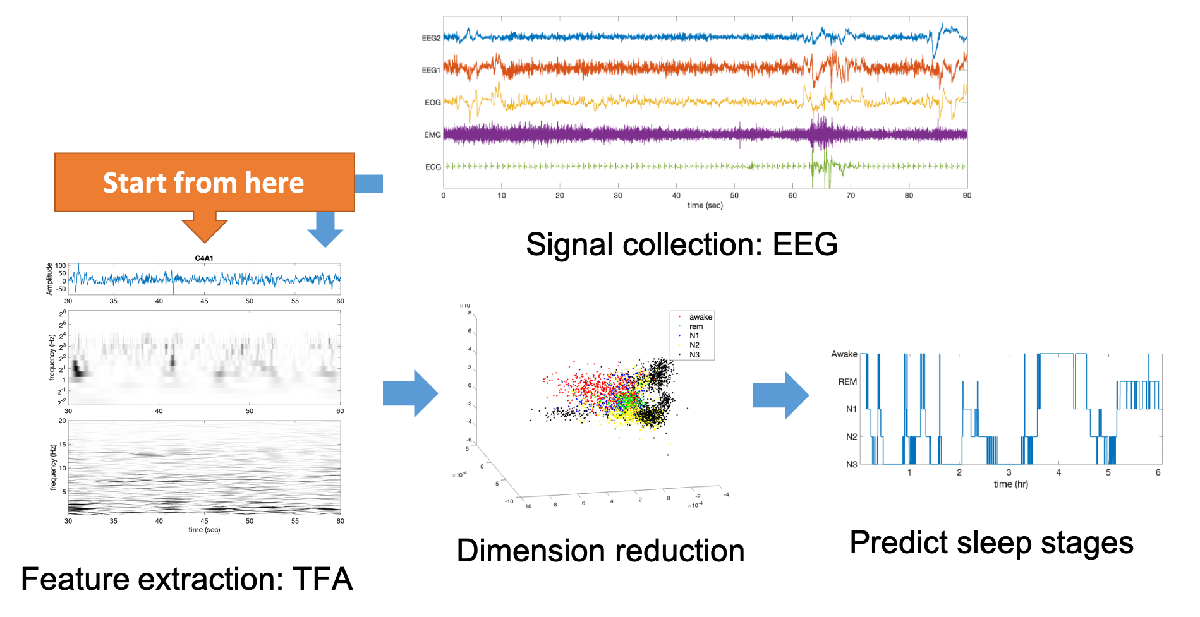

clc; clear; close all;
num_eigvec = 30; % how many feature you hope to use (default: 30)
% addpath('../src', '../data')
abs_cur_dic = fileparts(fullfile(pwd));
addpath([abs_cur_dic, '/data'])
addpath([abs_cur_dic, '/src'])
addpath([abs_cur_dic, '/demo'])
load("EEG_spectrum.mat")
n = size(X, 1);
Y_hot = zeros(n, 3);
for i = 1:5
    Y_hot(Y==i, i) = 1;
end

% Dimension reduction by DM
[U, S] = DMap4EEG(X, num_eigvec);

The kernel bandwidth is 21.6424.


% split train and validation set
train_ratio = 0.8;
[train_idx, val_idx] = Split_Set(n, train_ratio);

% SVM
template = templateSVM('KernelFunction', 'gaussian', ...
    'PolynomialOrder', [], 'KernelScale', 10, ...
    'BoxConstraint', 1, 'Standardize', true);

model = fitcecoc(U(val_idx, :), Y(val_idx, :), ...
    'Learners', template, ...
     'Coding', 'onevsone', ...
     'ClassNames', [1; 2; 3; 4; 5]);
 
[~, train_scores] = predict(model, U(train_idx, :));
[~, conf_mat] = confusion(Y_hot(train_idx, :)', train_scores');

acc = sum(diag(conf_mat)) / sum(conf_mat(:));
disp(['Training accuracy = ' num2str(acc)])

Training accuracy = 0.84426



[~, val_scores] = predict(model, U(val_idx, :));
[~, conf_mat] = confusion(Y_hot(val_idx, :)', val_scores');

[cell_info, ~, ~, ~] = CM2Info(conf_mat, {'Aw', 'REM', 'N1', 'N2', 'N3'});
disp('The following is confusion matrix of validation set')

The following is confusion matrix of validation set


disp(cell_info)

  Columns 1 through 7

    {0×0 double        }    {'Predict-Aw'}    {'Predict-REM'}    {'Predict-N1'}    {'Predict-N2'}    {'Predict-N3'}    {'PR'      }
    {'Target-Aw (21%)' }    {'166 (89%)' }    {'10 (5%)'    }    {'7 (4%)'    }    {'3 (2%)'    }    {'0 (0%)'    }    {[  0.9326]}
    {'Target-REM (16%)'}    {'3 (2%)'    }    {'133 (96%)'  }    {'0 (0%)'    }    {'3 (2%)'    }    {'0 (0%)'    }    {[  0.8061]}
    {'Target-N1 (8%)'  }    {'8 (12%)'   }    {'15 (22%)'   }    {'32 (47%)'  }    {'13 (19%)'  }    {'0 (0%)'    }    {[  0.8205]}
    {'Target-N2 (41%)' }    {'1 (0%)'    }    {'7 (2%)'     }    {'0 (0%)'    }    {'356 (98%)' }    {'1 (0%)'    }    {[  0.9013]}
    {'Target-N3 (15%)' }    {'0 (0%)'    }    {'0 (0%)'     }    {'0 (0%)'    }    {'20 (15%)'  }    {'114 (85%)' }    {[  0.9913]}
    {0×0 double        }    {0×0 double  }    {0×0 double   }    {0×0 double  }    {0×0 double  }    {0×0 double  }    {0×0 double}
    {'Accuracy: 0.898' }    {0×0 double  }    {0×0 do